**Punto A**

%%Aplicando las propiedades 
clear all;
close all;
clc;
Fs = 210;       %Frecuencia de muestreo
t = -1:1/Fs:2;  %Vector de tiempo
L = 3000;       %Longitud de la señal 
A = 3;          %Escalar
X = A*((4/3)*t-2/3);%Señal multiplicada por escalar
Y= fft(X,L);    %Transformada rápida

P = abs(Y/Fs);
f = linspace(0,Fs,numel(P));

plot(f,P)
axis ([0 5 0 3])
title('Gráfica fft ')
xlabel('Frecuencia')
ylabel('|P(f)|')


syms t f;       %Variables simbólicas
escal=4;
x= escal*((4/3)*t-2/3);  %Señal por escalar
m=int(x*exp(-1i*2*pi*f*t),t,-1,2) %Transformada de Fourier teórica

$$m = \frac{4\,{\mathrm{e}}^{-4\,\pi \,f\,\mathrm{i}}\,\left(1-{\mathrm{e}}^{6\,\pi \,f\,\mathrm{i}}+3\,\pi \,f\,\mathrm{i}+3\,\pi \,f\,{\mathrm{e}}^{6\,\pi \,f\,\mathrm{i}}\,\mathrm{i}\right)}{3\,f^{2}\,\pi^{2}}$$

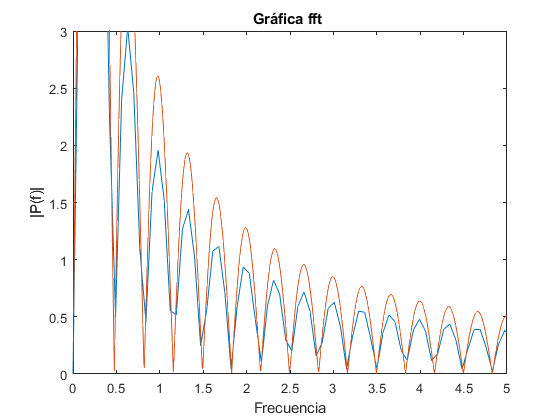

hold on         %sobreposición
fplot(f,abs(m),[0 5])